load("../data/train_graphs.mat")
train_graphs

train_graphs = 29943×3 table
      Features        Adjacency      y
    _____________    ____________    _

    {22×1 single}    {22×22 int8}    0
    {19×1 single}    {19×19 int8}    0
    {20×1 single}    {20×20 int8}    0
    {17×1 single}    {17×17 int8}    0
    {17×1 single}    {17×17 int8}    0
    {15×1 single}    {15×15 int8}    0
    {28×1 single}    {28×28 int8}    0
    {18×1 single}    {18×18 int8}    0
    {20×1 single}    {20×20 int8}    0
    {24×1 single}    {24×24 int8}    0
    {13×1 single}    {13×13 int8}    0
    {18×1 single}    {18×18 int8}    0
    {23×1 single}    {23×23 int8}    0
    {24×1 single}    {24×24 int8}    0
    {17×1 single}    {17×17 int8}    0
    { 8×1 single}    { 8×8  int8}    0


features_table = train_graphs.Features;
edges_table = train_graphs.Adjacency;
targets_table = train_graphs.y;

%% Parameters
inputSize = 1;
numClasses = 2;
hiddenSize = 64;

parameters = initialize_params_glorot(inputSize,hiddenSize);
%parameters = initialize_params_randn(inputSize,hiddenSize);

%% Train Hyperparameters
numEpochs = 10;
learnRate = 0.001;
velocity = [];
momentum = 0.9;

numTrain = 29000

numTrain = 29000

batchSize = 100

batchSize = 100

numBatches = numTrain/batchSize

numBatches = 290

epoch = 0;
% Loop over epochs.
while epoch < numEpochs
    shuffle_idx = randperm(height(train_graphs));
    epoch = epoch + 1;
    for batch=1:numBatches
        features = [];
        numNodesPerGraph = [];
        edges = [];
        targets = [];
        for i=1:batchSize
            index = shuffle_idx(i+(batch-1)*batchSize);
            features = [features; cell2mat(features_table(index))];
            numNodesPerGraph = [numNodesPerGraph (length(cell2mat(features_table(index))))];
            edges = blkdiag(edges,cell2mat(edges_table(index)));
            %targets = [targets; [targets_table(index) abs(1-targets_table(index))]];
            targets = [targets; targets_table(index)];
        end
        features = dlarray(features);
        numNodes = sum(numNodesPerGraph);
        edges = dlarray(boolean(edges));
        targets = double(targets);
        % Evaluate the model loss and gradients using dlfeval and the
        % modelLoss function
        tic
        [loss,gradients] = dlfeval(@modelLoss,parameters,features,edges,targets,numNodesPerGraph);
        toc
        % Update the network parameters using the SGDM optimizer.
        [parameters,velocity] = sgdmupdate(parameters,gradients,velocity,learnRate,momentum);
        %gradients.layer2.lin_l_bias
        %gradients.classifier.weights
        %gradients.classifier.bias
    end
    %Display loss at end of epoch
    fprintf("Epoch: %d, Loss: %f \n", epoch, loss);
end

Elapsed time is 0.501614 seconds.
Elapsed time is 0.253339 seconds.
Elapsed time is 0.309535 seconds.
Elapsed time is 0.260694 seconds.
Elapsed time is 0.408969 seconds.
Elapsed time is 0.597768 seconds.
Elapsed time is 0.422740 seconds.
Elapsed time is 0.225646 seconds.
Elapsed time is 0.325277 seconds.
Elapsed time is 0.299452 seconds.


%Quick test to see what the network's doing

numQuickTest = 300

numQuickTest = 300

features = [];
numNodesPerGraph = [];
edges = [];
targets = [];
new_shuffle_idx = randperm(height(train_graphs));
for i=1:numQuickTest
    index = new_shuffle_idx(i);
    features = [features; cell2mat(features_table(index))];
    numNodesPerGraph = [numNodesPerGraph (length(cell2mat(features_table(index))))];
    edges = blkdiag(edges,cell2mat(edges_table(index)));
    targets = [targets; targets_table(index)];
end
features = dlarray(features);
edges = dlarray(boolean(edges));
targets = double(targets);

results= model(parameters,features,edges,numNodesPerGraph);
roundresults = round(extractdata(results))

roundresults = 1×300 single row vector
     0     1     1     0     1     1     1     1     0     1     1     0     1     0     0     1     1     1     0     1     1     0     1     1     0     0     0     0     1     0     0     0     1     0     1     0     1     0     1     0     1     1     1     0     1     1     0     1     1     1


targets'

ans =      1     0     0     1     1     0     0     1     1     1     1     0     1     0     0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     1     1     1     0     1     0     1     0     1     1     1     1     0     1     0     0     1     1


acc = nnz(round(extractdata(results))==targets')/numQuickTest

acc = 0.6833

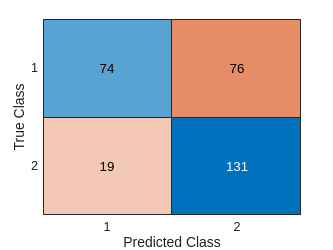

m = confusionmat(single(targets),roundresults);
confusionchart(m)

%load("../models/modelparams.mat","parameters");

load("../data/test_graphs.mat")
test_graphs

test_graphs = 29950×3 table
      Features        Adjacency      y
    _____________    ____________    _

    {15×1 single}    {15×15 int8}    0
    {16×1 single}    {16×16 int8}    0
    {20×1 single}    {20×20 int8}    0
    {20×1 single}    {20×20 int8}    0
    {21×1 single}    {21×21 int8}    0
    {23×1 single}    {23×23 int8}    0
    {22×1 single}    {22×22 int8}    0
    {20×1 single}    {20×20 int8}    0
    {19×1 single}    {19×19 int8}    0
    {20×1 single}    {20×20 int8}    0
    {23×1 single}    {23×23 int8}    0
    { 9×1 single}    { 9×9  int8}    0
    {24×1 single}    {24×24 int8}    0
    {17×1 single}    {17×17 int8}    0
    {13×1 single}    {13×13 int8}    0
    {19×1 single}    {19×19 int8}    0


numTest = 300;
trues = zeros([1 numTest]);
preds = zeros([1 numTest]);

new_shuffle_idx = randperm(height(test_graphs));
for i=1:numTest
    index = new_shuffle_idx(i);
    features = cell2mat(test_graphs.Features(index));
    features = dlarray(features);
    edges = cell2mat(test_graphs.Adjacency(index));
    edges = dlarray(boolean(edges));
    targets = test_graphs.y(index);
    targets = double(targets);
    trues(i) = targets;
    numNodes = length(features);
    preds(i) = model(parameters,features,edges,numNodes);
end


roundpreds = round(preds)

roundpreds =      1     1     0     1     1     1     0     1     1     1     0     1     0     0     1     1     0     0     1     1     0     1     1     1     1     0     1     1     0     1     0     1     0     0     1     1     0     0     1     1     0     0     1     0     1     0     1     1     0     0


accuracy=nnz(trues==round(preds))/numTest

accuracy = 0.7900

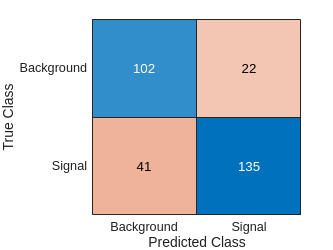

%mtest = confusionmat(trues,roundpreds);

classNames = {'Background', 'Signal'};
predicted_classes = categorical(roundpreds,[0.0 1.0],classNames);
true_classes = categorical(trues,[0.0 1.0],classNames);
confusionchart(predicted_classes,true_classes)

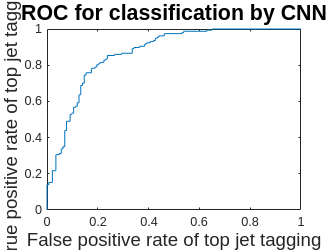


[X,Y,~,AUC] = perfcurve(trues,preds,1.0);
plot(X,Y)
xlabel('False positive rate of top jet tagging','fontsize',14);
ylabel('True positive rate of top jet tagging','fontsize',14);
title('ROC for classification by CNN','fontsize',16)

AUC

AUC = 0.8689

save("../models/modelparams.mat","parameters");